clear all; close all;
[rav, rav_emotions] = ravdess_database();
%[emdb, emdb_emotions] = berlin_emotional_database();
%hum = humaine();

labels = unique(rav_emotions);
num_emotions = number_emotions(rav_emotions, labels);

rav.Labels = 1:length(rav.Files);
%emdb.Labels = 1:length(emdb.Files);
%hum.Labels = 1:length(hum.Files);

%rav_info = audioinfo(rav.Files{1,1});
fs = 8000;

%new_emdb = transform (emdb, @(x,info) resample_datastore(x, info, ...
%                               fs), 'IncludeInfo', true);
%new_hum = transform (emdb, @(x,info) resample_datastore(x, info, ...
%                                fs), 'IncludeInfo', true);


%ads = combine(rav, new_emdb, new_hum);
%shAds = shuffle(ads);
%subAds1 = partition(shAds,3,1);
%subAds2 = partition(shAds,3,2);
%subAds3 = partition(shAds,3,3);

% extracts a vector of features and returns their names and idxs 
[features, feature_idxs, feature_names] = extract_features(rav, fs, length(rav.Files));
[num_of_features, ~] = size(features);

% extracts stats by the vector stats2extract and assigns an emotion to each
% speech segment
stats2extract = 1:18;
num_of_stats = numel(stats2extract);
[stats, stat_names] = extract_stats(features, stats2extract, num_emotions, num_of_features);



% fz = 1;
% sp = zeros(szr,min*col+1);
% for e = 1:szc
%     s = size(features{1,e});
%     f(fz:fz+s(1)-1,1:s(2)) = features{1,e};
%     f(fz:fz+s(1)-1, s(2)+1) = num_emotions(e);
%     conc = f(fz:fz+min-1, 1:s(2));
%     sp(e,1:end-1) = conc(:)';
%     sp(e,end) = num_emotions(e);
%     
%     fz = fz + s(1);
% end

% filters out the nan and inf values
stats = filter_nan_inf(stats);

% calculates the relieff algorithm and the returns the weights and idxs  
k = 60;
[weights, idxs] = relieff_weights(stats, rav_emotions, k);

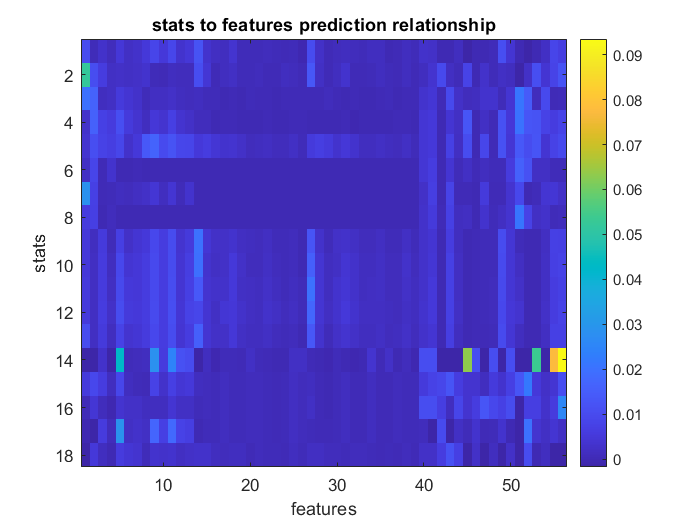

% creates a weight matrix and draws it using imagesc with weights denoted
% by a color bar
weight_matrix = create_weight_matrix(weights, num_of_features, num_of_stats);

imagesc(weight_matrix);
colorbar;
title("stats to features prediction relationship");
xlabel("features");
ylabel("stats");

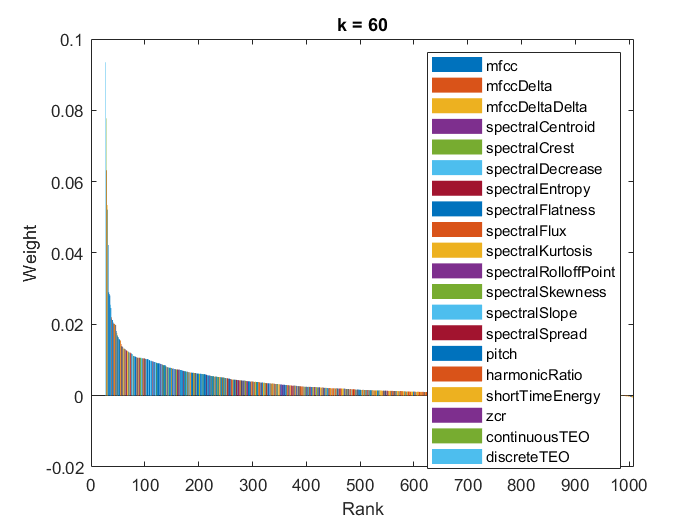

% creates a sorted weight bar graph that illustrates the rank of each stat
% and feature in classification  
sorted_weights_bar(weight_matrix, feature_idxs, feature_names, k);

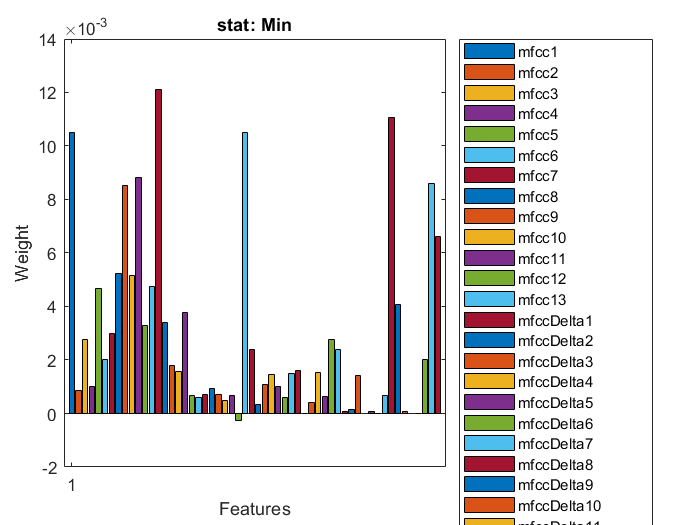

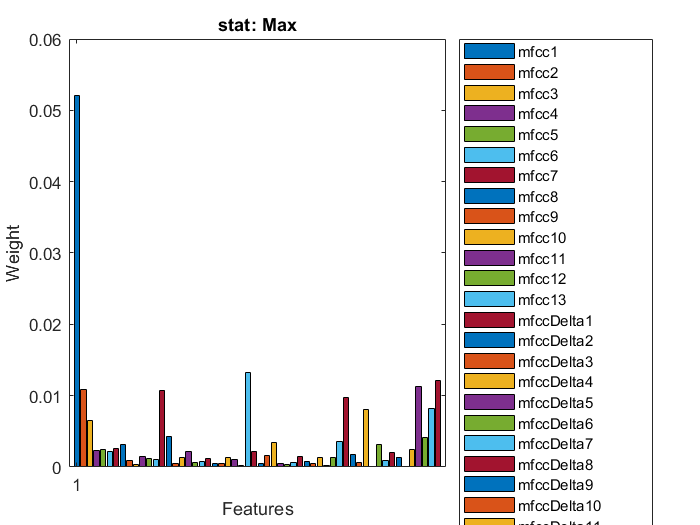

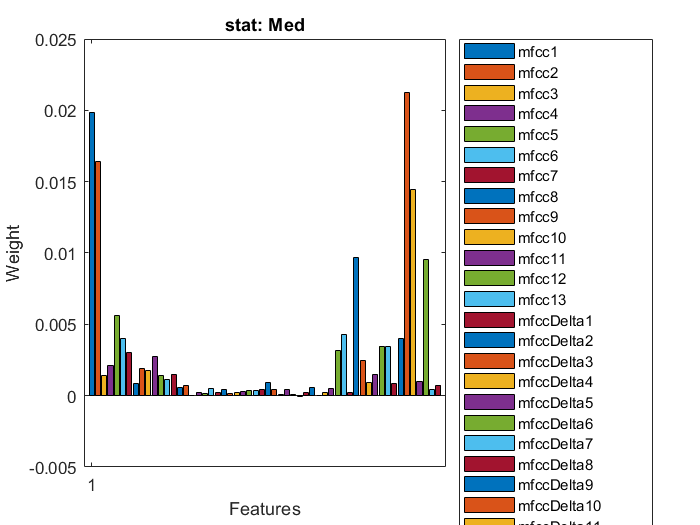

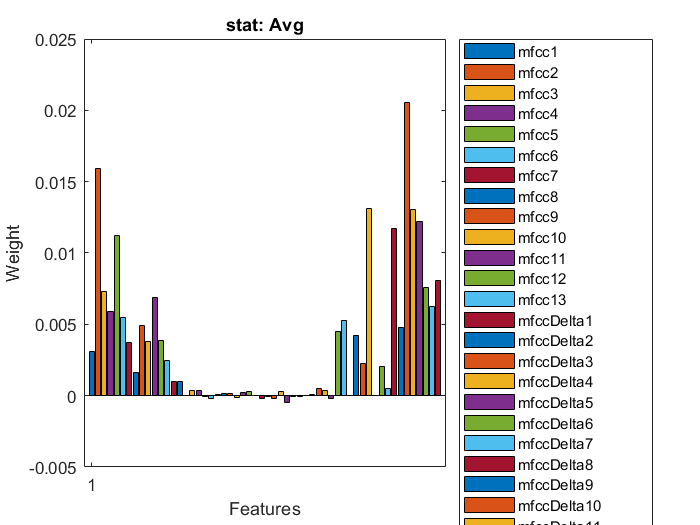

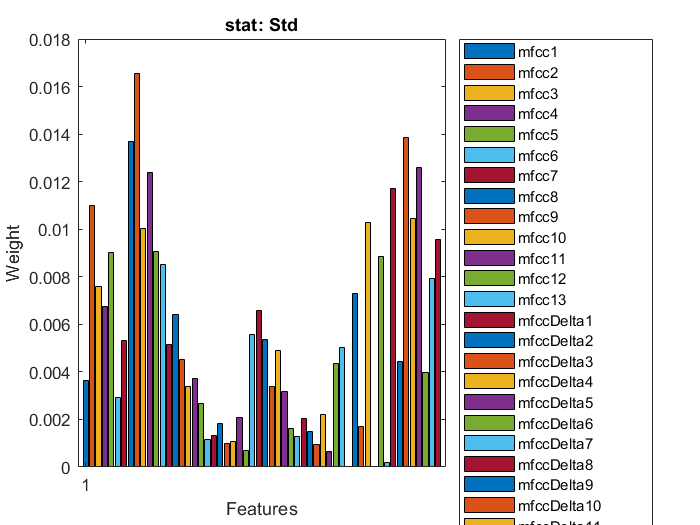

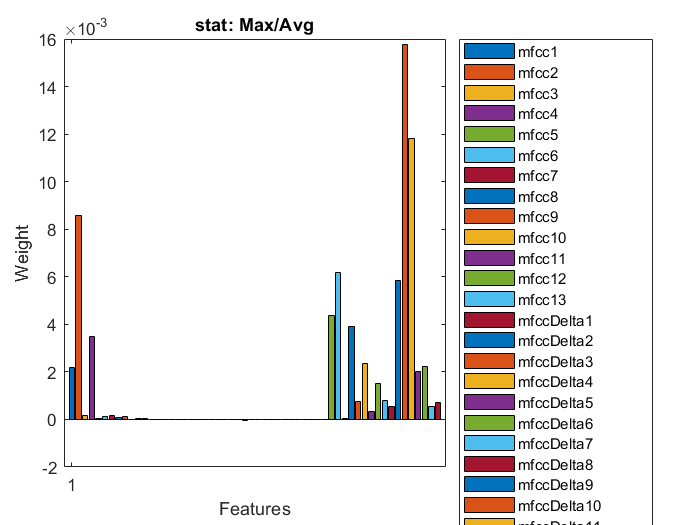

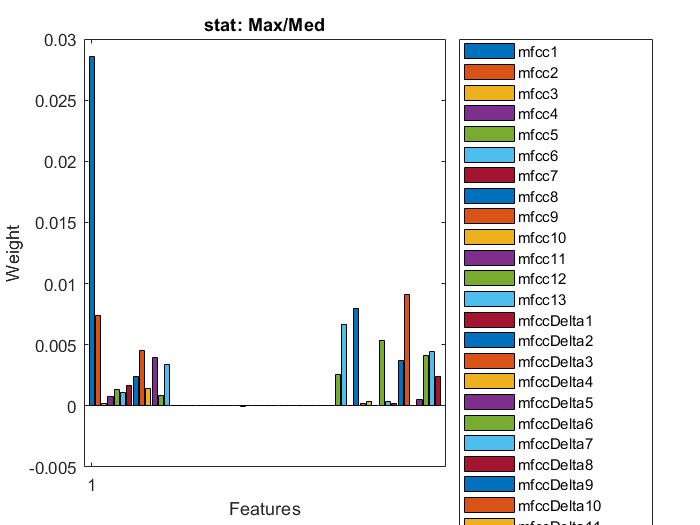

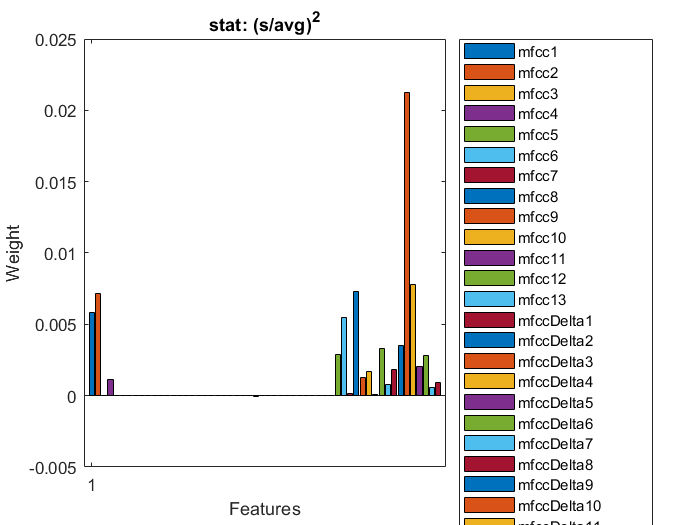

% creates sub bar graphs to zoom in on each stat independently
sub = sub_names(feature_names, feature_idxs, num_of_features);
sub_weight_bars(weight_matrix, sub, stat_names);


% returns the stat, feature combinations that are above the threshold value
thr = 0.005;
[optimum_stats, optimum_names] = weight_thr(stats, weight_matrix, thr, feature_names, stat_names, feature_idxs);



cnt = 1;
for s = 1:size(optimum_names, 2)
    if (contains(optimum_names{1, s}(1),'teo'))
        opt_ind_teo(cnt) = s;
        cnt = cnt + 1;
    end
end

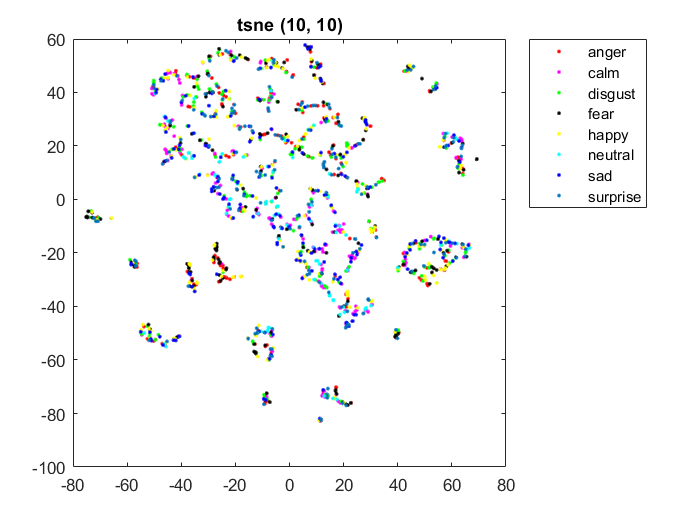


% plots the scattering of emotion points in 2D space using t-sne
exaggeration = 10;
perplexity = 10;
plot_tsne(optimum_stats, labels, exaggeration, perplexity);

% partition data
train_idxs = randsample(1440, 1000);
trainingData = optimum_stats(:, train_idxs);
test_idxs = 1:size(optimum_stats, 2);
test_idxs(train_idxs) = [];
testData = optimum_stats(1:end-1, test_idxs);


% train classifier
[trainedKNN, validationAccuracyKNN] = trainKNNClassifier(trainingData);
[trainedSVM, validationAccuracySVM] = trainSVMClassifier(trainingData);


% test classifier
yfitKNN = trainedKNN.predictFcn(testData);
incorrect_idxs_knn = find_incorrect_indices(yfitKNN, num_emotions, test_idxs);
accuracy_knn = (numel(yfitKNN) - numel(incorrect_idxs_knn)) / numel(yfitKNN);

yfitSVM = trainedSVM.predictFcn(testData);
incorrect_idxs_svm = find_incorrect_indices(yfitSVM, num_emotions, test_idxs);
accuracy_svm = (numel(yfitSVM) - numel(incorrect_idxs_svm)) / numel(yfitSVM);

incorrect_matrix_svm = cell(size(incorrect_idxs_svm, 1) + 1, 3);
incorrect_matrix_svm{1, 1} = "segment number indices";
incorrect_matrix_svm{1, 2} = "expected";
incorrect_matrix_svm{1, 3} = "actual";
for inc = 2:size(incorrect_idxs_svm) + 1
    incorrect_matrix_svm{inc, 1} = incorrect_idxs_svm(inc - 1);
    incorrect_matrix_svm{inc, 2} = rav_emotions(incorrect_idxs_svm(inc - 1)); 
    incorrect_matrix_svm{inc, 3} = num2name(yfitSVM(incorrect_idxs_svm(inc - 1)), labels);
end

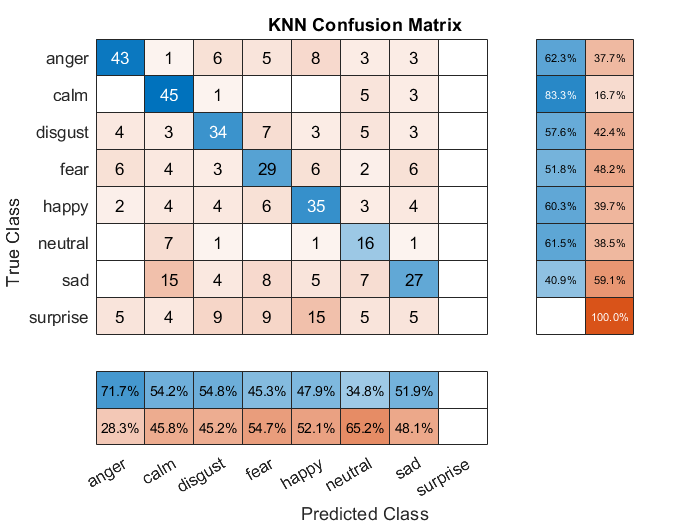

% plot confusion chart
figure;
cm_knn = confusionchart(categorical(num2name(num_emotions(test_idxs, :), labels)), categorical(num2name(yfitKNN, labels)), ...
    "ColumnSummary", 'column-normalized', "RowSummary", "row-normalized");
cm_knn.Title = "KNN Confusion Matrix";

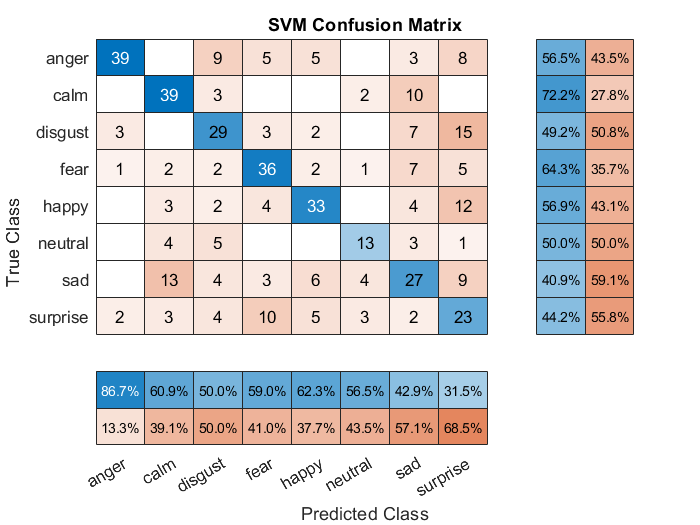

figure;
cm_svm = confusionchart(categorical(num2name(num_emotions(test_idxs, :), labels)), categorical(num2name(yfitSVM, labels)), ...
    "ColumnSummary", 'column-normalized', "RowSummary", "row-normalized");
cm_svm.Title = "SVM Confusion Matrix";